# Whale Path Visualization

This script performs a group calculation to find range of latitude values for each whale in the Blue Whale dataset. Then, a single whale is selected and the path for that whale is visualized on a map.

load cleanWhaleData whales
whalesSummary = groupsummary(whales,"ID","range","latitude");
whalesSummary = sortrows(whalesSummary,'range_latitude','descend')

whalesSummary = 140x3 table
           ID           GroupCount    range_latitude
    ________________    __________    ______________

    2008CA-Bmu-04176       259            34.652    
    2007CA-Bmu-01385       264            34.495    
    2005CA-Bmu-10821       276            33.208    
    2000CA-Bmu-01386       186            31.687    
    2000CA-Bmu-01390       126             30.58    
    2004CA-Bmu-04175       177            29.387    
    2005CA-Bmu-01390       260            28.747    
    2005CA-Bmu-10829       309            28.647    
    2000CA-Bmu-10828        20            28.432    
    2006CA-Bmu-02083       329            27.998    
    1998CA-Bmu-10823       226            27.936    
    1999CA-Bmu-04172       166            27.396    
    2000CA-Bmu-10832       265            26.931    
    2007CA-Bmu-23043       194            25.964    
    2007CA-Bmu-05801 

Select a whale from the dataset

whalesID = string(whalesSummary.ID);
id = whalesID(136)

id = "1999CA-Bmu-00845"

rowsToKeep = whales.ID==id;
whale = whales(rowsToKeep,:)

whale = 1x8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensor_type        manually_marked_outlier
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    _______________________

    1999CA-Bmu-00845    1999-10-10 22:25:38.000     -120.69      33.992           B                  2             argos-doppler-shift              ""           


Visualize the path on a map

numPoints = height(whale)

numPoints = 1

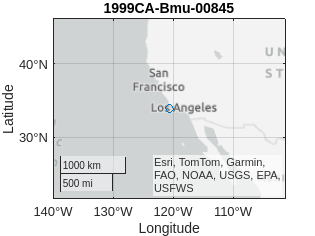

if numPoints < 10
    geoplot(whale.latitude,whale.longitude, "o")
elseif numPoints < 100
    geoplot(whale.latitude,whale.longitude, "o-")
else
    geoplot(whale.latitude,whale.longitude, "-")
end
title(id)

*Copyright 2021 The MathWorks, Inc.*

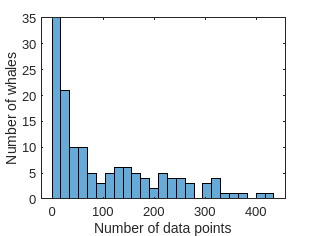

histogram(whalesSummary.GroupCount,25)
xlabel("Number of data points");
ylabel("Number of whales");